% code for plot results of Widefield imaging, which contain functions listed
% below
% Align neural activity of different trails by behavior events
% plot aligned neural activity of each trial (line + heatmap)
% plot activity correlation of each brain region
% plot neural activity sequence averaged by specific timebin
% plot neural activity averaged by specific behavior

% cut and align the neural activity based on task event written by NY

clear all;
close all;
clc;

Animal = 's19';
Date = '20200928';
totalTrial = 150;
Key = 'heavy90';
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])

Error using load
Unable to find file or directory 'D:\Doya_rotation\20200928_s19_heavy90\s19_behavior_20200928_heavy90.mat'.

behavior_data = behavior_neural_time_convolved_zscored;

neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));


% clear all;
% close all;
% clc;
% 
% CompNum = 40;
% 
% Initial = 'NY';
% Animal = 'tlx56';
% Date = '221219';
% totalBlock = 10;
% Key = 'min';
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

fps = 20;
% make sure the order of the rows in the table should line up with the order of the names in the imaging file
timepoints_table = readtable([working_directory Date filesep Initial '_' Animal filesep 'BehaviorRecord.csv'],'NumHeaderLines',1);
before = 1000;
after = 4000;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% load neural activity data
cd([working_directory Date filesep Initial '_' Animal filesep 'ICA\ICA_40']);
load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_Temp','-mat');

% cut and align each data
% how to deal with data which do not contain enough before or after
% timepoints
% colum 23: lift-1sec (ms)
timepoints = [table2array(timepoints_table(1:totalBlock,23))*fps/1000 table2array(timepoints_table(1:totalBlock,23))*fps/1000+(before+after)*fps/1000];
% in case there are float (not occured usually)
timepoints = round(timepoints);

% save aligned data 
% set Events to fit the style of CR_Reconstruction.mlx

RecICA_lift{totalBlock} = [];
for block = 1:totalBlock
    disp(['Calculating imaging block ' num2str(block)]);
    RecICA_lift{block} = RecICA_Temp{block}(:,timepoints(block,1):timepoints(block,2));
end

Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 3
Calculating imaging block 4
Calculating imaging block 5
Calculating imaging block 6
Calculating imaging block 7
Calculating imaging block 8
Calculating imaging block 9
Calculating imaging block 10



save([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_lift','-append');

% Plot neural activity of each trial and make activity correlation matrix from RecICA_lift written by NY

CompNum = 40;
Animal = 'tlx56';
Date = '221219';
Events = {'lift'}; % 'lift' or 'Temp'
Initial = 'NY'; 
Key = 'min';
Block = 10;
totalBlock = 10;
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

close all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% load neural activity data
cd([working_directory Date filesep Initial '_' Animal ])
addpath([working_directory Date filesep Initial '_' Animal filesep 'ICA\ICA_40']);
load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_Temp','RecICA_lift','-mat');
samp_img = reshape(RecICA_lift{Block},[128 128 size(RecICA_lift{Block}, 2)]);
mkdir([working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs'])
output_dir = [working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs' filesep];
imwrite(samp_img(:,:,1),[output_dir sprintf('RecICA_lift_%d.png', Block)]);

% set ROI to compare neural activity
brain_roi_name = ['A' 'B' 'C' 'D' 'E' 'F']

brain_roi_name = 'ABCDEF'

brain_roi = [[63, 11]; [73, 12]; [30, 59];  [107, 66]; [45, 93]; [89, 94]];
y_reverse = 1; % 1 if brain_roi is specified by ImageJ
% set how many pixels expand
pix_exp = 2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
brain_roi_temp = brain_roi;
if y_reverse == 1
    for i = 1:length(brain_roi)
        brain_roi(i,1) = brain_roi_temp(i,2);
        brain_roi(i,2) = brain_roi_temp(i,1);
    end
end

% calculate neural activity of each roi
roi_activities = zeros(length(brain_roi), totalBlock, size(RecICA_lift{Block}, 2));

for j = 1:totalBlock
    RecICA_lift_reshape = reshape(RecICA_lift{j},[128 128 size(RecICA_lift{j}, 2)]);
%     roi_activities = zeros(length(brain_roi),size(RecICA_Temp{j}, 2));
    % expand roi
    for i = 1:length(brain_roi)    
        roi_RecICA_lift = RecICA_lift_reshape(brain_roi(i,1)-pix_exp:brain_roi(i,1)+pix_exp, brain_roi(i,2)-pix_exp:brain_roi(i,2)+pix_exp, :); 
        % take mean of neural activity
        mean_roi_activity = reshape(mean(mean(roi_RecICA_lift)),[1 size(RecICA_lift{j}, 2)]);
        roi_activities(i,j,:) = mean_roi_activity;
    end
end

% calculate Block mean of neural activity of each roi
block_mean_roi_activities = reshape(mean(roi_activities,2),[size(roi_activities, 1) size(roi_activities, 3)]);

% calculate correlation of neural activity
mean_RecICA_lift = zeros(size(RecICA_lift{1}));
for j = 1:totalBlock
    mean_RecICA_lift = mean_RecICA_lift + RecICA_lift{j};
end
mean_RecICA_lift = mean_RecICA_lift/totalBlock;
R_roi_act = zeros(length(brain_roi), 128*128);
for i = 1:length(brain_roi)
    for k = 1:128*128
        temp_coeff = corrcoef(transpose(block_mean_roi_activities(i,:)), transpose(mean_RecICA_lift(k,:)));
        R_roi_act(i,k) = temp_coeff(2,1);
    end
end

% plot neural activity of specific brain region
ylimit = [-0.1 0.2];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
addpath([working_directory 'PCA_and_ICA\Subaxis']);
figure
for i = 1:length(brain_roi) 
    subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    for j = 1:totalBlock
        hold on 
        r = plot(-1:0.05:4,squeeze(roi_activities(i,j,:)));
        hold off
    end
    alpha(r,0.1);
    hold on
    b = plot(-1:0.05:4,block_mean_roi_activities(i,:));
    title([brain_roi_name(i)], 'FontSize',6);
    ylim(ylimit); 

end

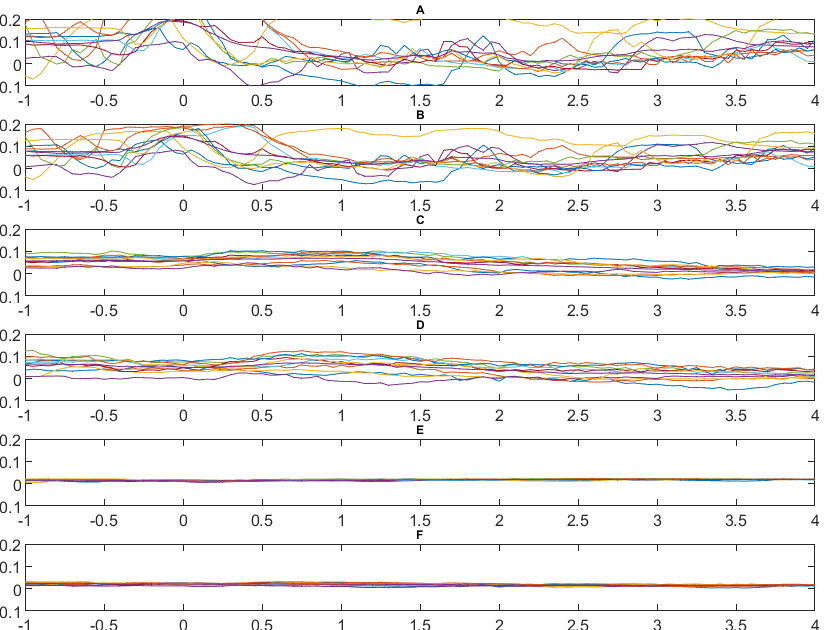

saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

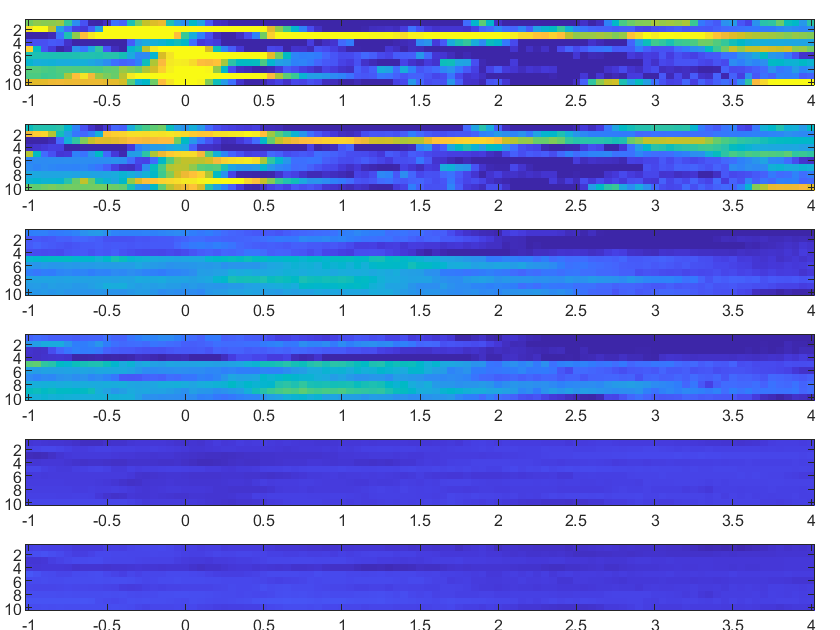

% plot neural activity heatmap of specific brain region
% x:time, y:blocks, color:df/f
climit = [0 0.2];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
set(gcf,'color','w');
for i = 1:length(brain_roi) 
    subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    imagesc(-1:0.05:4,1:10,image,clims);
end

filename = [output_dir Animal, '_' num2str(clims(2)) '_all_activity_heatmap.png'];
saveas(gcf,filename);

close all;

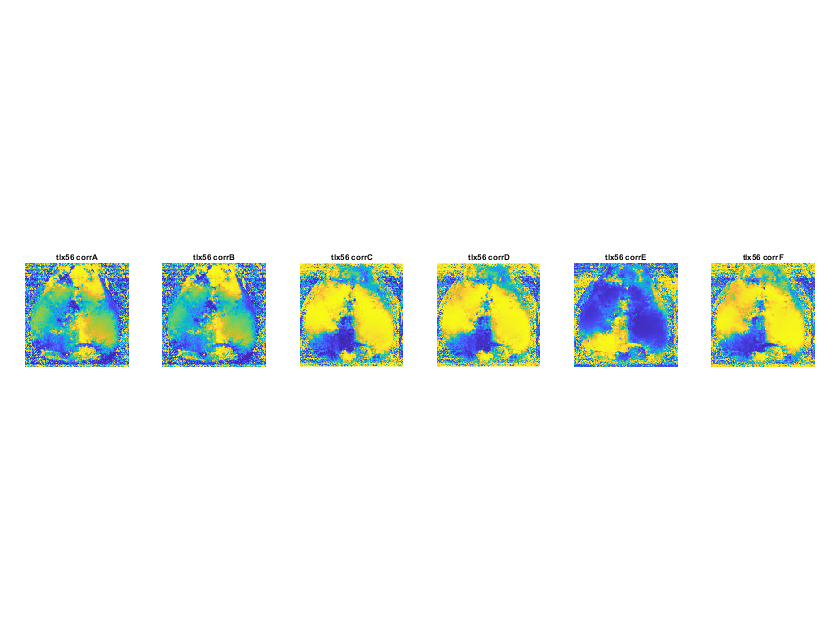

% plot correlation heatmap

figure
set(gcf,'color','w')
for i = 1:length(brain_roi)
    subaxis(1,length(brain_roi),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
    clims = [-1 1]; 
    image = R_roi_act(i,:);
    imagesc(reshape(image,[128 128]),clims)
    axis square
    axis off
    title([Animal ' corr' brain_roi_name(i)], 'FontSize',4);
end
saveas(gcf,[output_dir Animal '_activity_correlation_map.png']);

% Output tiff images from matrix for visualization written by NY
clear all;
close all;
clc;

CompNum = 40;

Initial = 'NY';
Animal = 'tlx56';
Date = '221219';
totalBlock = 10;
Block = 8;
Key = 'min';
Event = 'lift'; % 'Temp'
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% for visualizing images after PCA/ICA
cd([working_directory Date filesep Initial '_' Animal filesep 'ICA\ICA_40']);
event_act = ['RecICA_' Event];
load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],event_act,'-mat');
mkdir(['RecICA_' Event '_out_' Key]);

if strcmp(Event, 'Temp')
    max(max(RecICA_Temp{Block}))
    target_RecICA = Rec_ICA_Temp;
elseif strcmp(Event, 'lift')
    max(max(RecICA_lift{Block}))
    target_RecICA = RecICA_lift;
end

ans = 0.4575

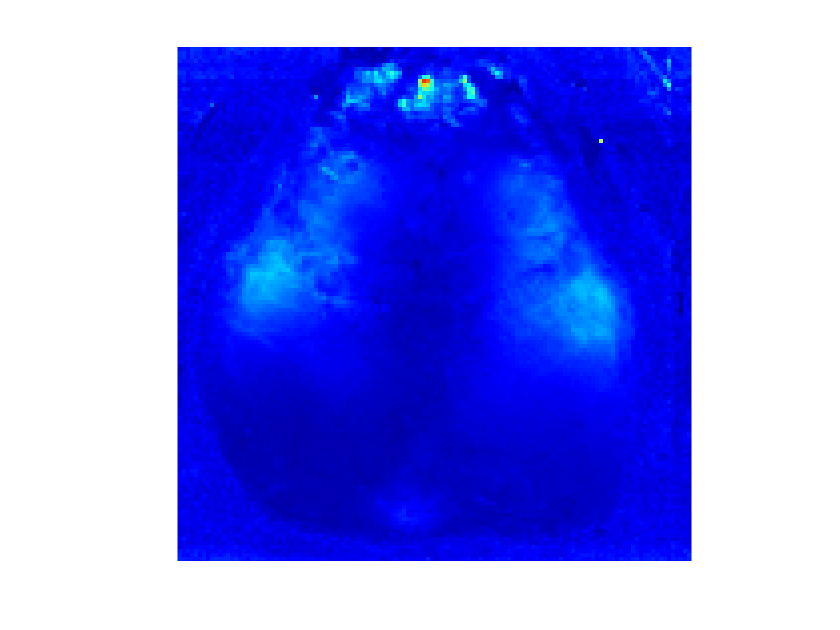

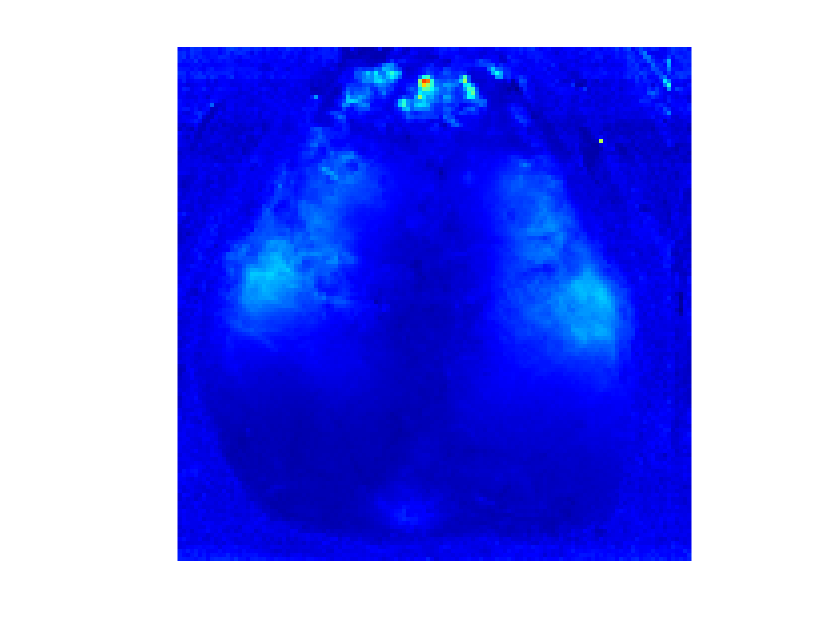

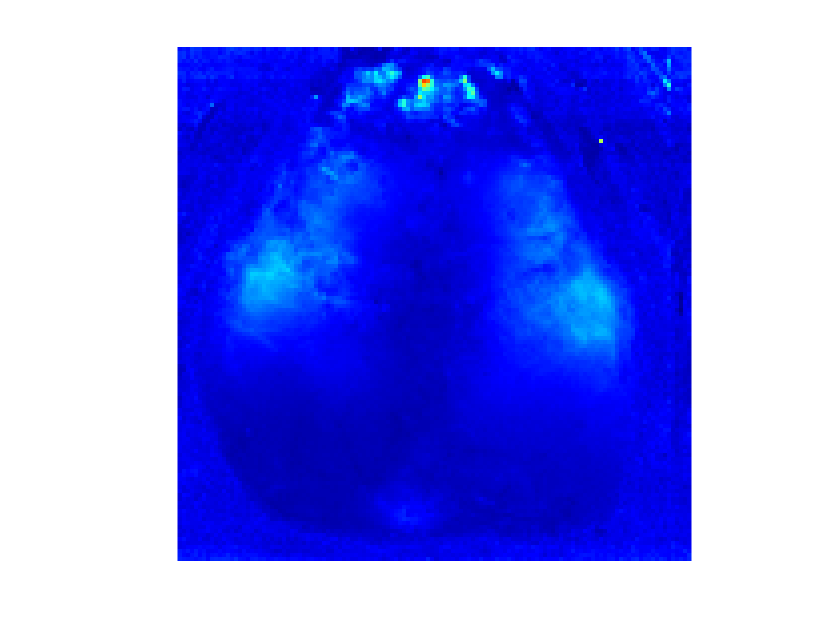

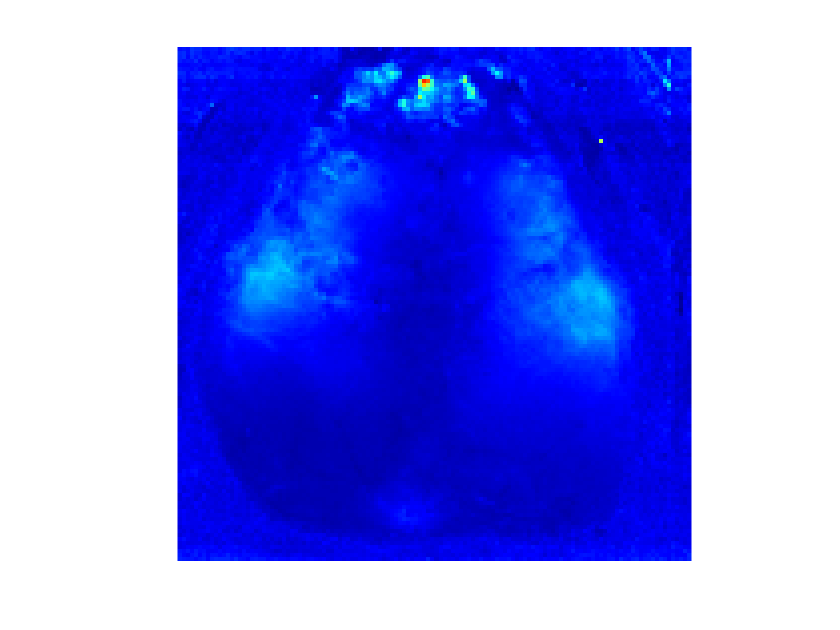

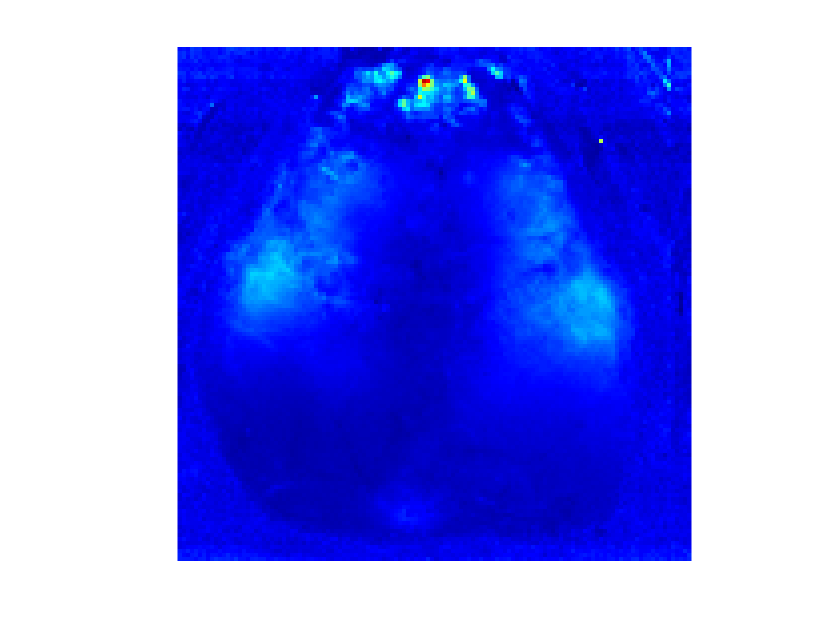

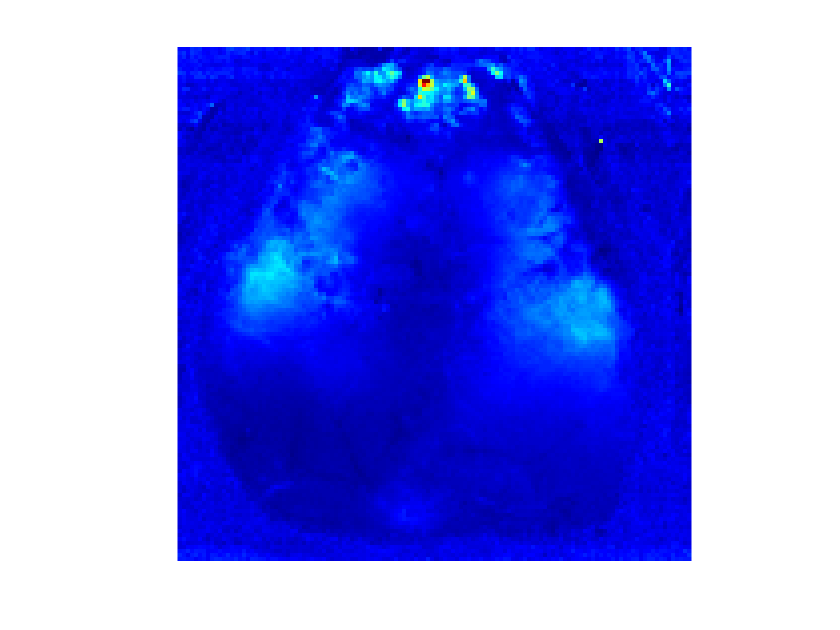

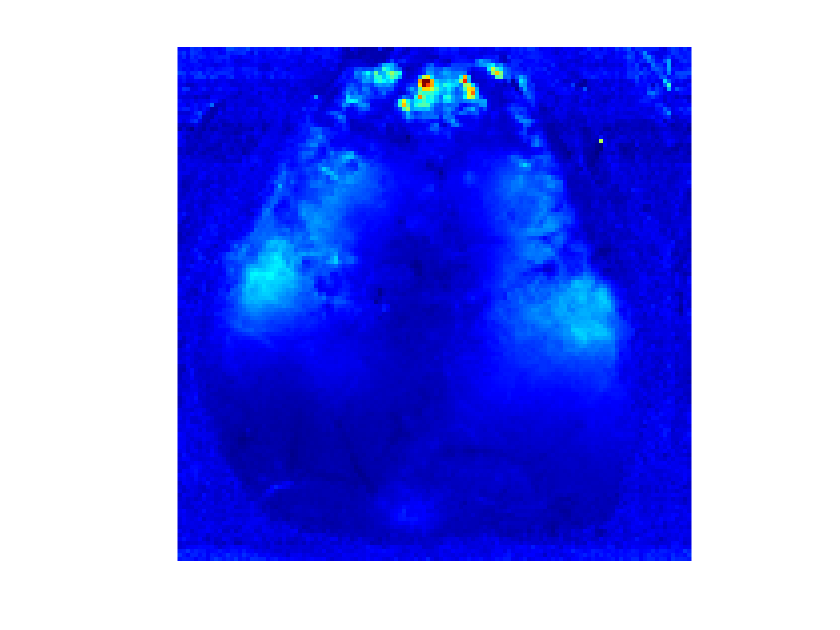

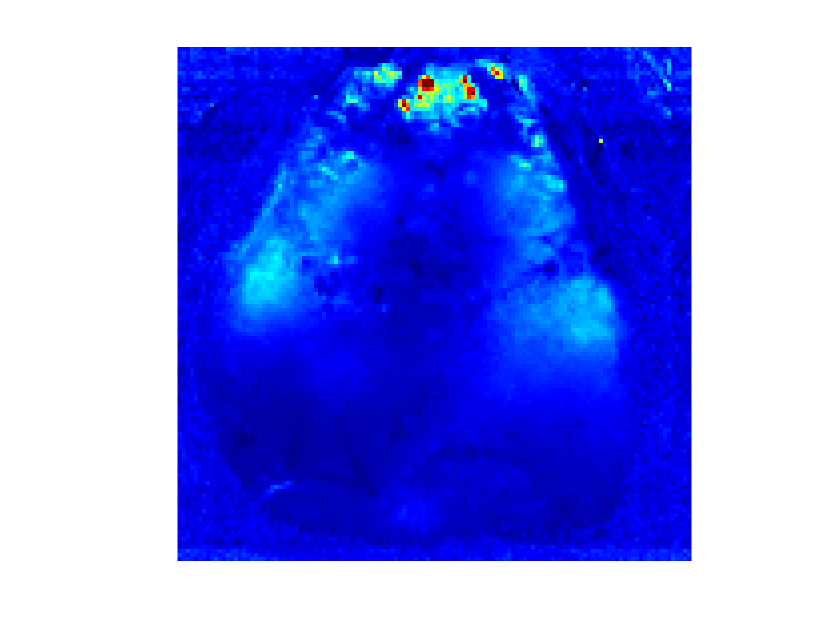

clims = [0 0.3]; % adjust by using max(max(RecICA_Temp{1})) (upper limit)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:size(target_RecICA{Block},2)
% for i = 1:size(RecICA_lift{Block},2)
    figure;
    set(gcf,'color','w');
    image = target_RecICA{Block}(:,i);
%     image = RecICA_lift{Block}(:,i);
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    filename = ['RecICA_' Event '_out_' Key filesep 'RecICA_' num2str(Block) '_', num2str(i), '.tif'];
    saveas(gcf,filename);
end

close all

% for visualization of event aligned sequence

fps = 20;
% Specify how many milliseconds before and after the event to plot and how many milliseconds between plots
before = 1000;
after = 4000;
inter = 50;
output_dir = [working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs' filesep];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% calculate block average RecICA neural activity

mean_RecICA_lift = zeros(size(RecICA_lift{1}));
for j = 1:totalBlock
    mean_RecICA_lift = mean_RecICA_lift + RecICA_lift{j};
end
mean_RecICA_lift = mean_RecICA_lift/totalBlock;
max(max(mean_RecICA_lift))

ans = 0.3590

clims = [0 0.2]; % adjust by upper limit

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot averaged neural activity sequences
addpath([working_directory 'PCA_and_ICA\Subaxis']);
figure;
set(gcf,'color','w');
for i = 17:36 %1:(before+after)/inter   
    subaxis(4,5,i-16, 'Spacing', 0.02, 'Padding', 0, 'Margin', 0.015);
    image = mean(mean_RecICA_lift(:,inter*(i-1)*fps/1000+1:inter*i*fps/1000),2);
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    title(['RecICA ' num2str(inter*(i-1)-before) ' ms'], 'FontSize',4);
end
saveas(gcf,[output_dir Animal '_' Event '_' Key '_' num2str(clims(2)) '_RecICA_sequence.png']);
close all

% for visualization of reaching event aligned sequence

fps = 20;
events = {'before' 'extend' 'grasp' 'wisdraw' 'after'};
timepoints_table = readtable([working_directory Date filesep Initial '_' Animal filesep 'BehaviorRecord.csv'],'NumHeaderLines',1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% colum 23: lift-1sec (ms)
timepoints = [table2array(timepoints_table(1:totalBlock,23))*fps/1000 table2array(timepoints_table(1:totalBlock,16))*fps/1000 table2array(timepoints_table(1:totalBlock,18))*fps/1000 table2array(timepoints_table(1:totalBlock,21))*fps/1000 table2array(timepoints_table(1:totalBlock,22))*fps/1000 table2array(timepoints_table(1:totalBlock,23))*fps/1000+(before+after)*fps/1000];
% in case there are float (not occured usually)
timepoints = round(timepoints);
% replace 0 to end (ms): table2array(timepoints_table(1:totalBlock,22))*fps/1000 
zero_idx = timepoints==0;
for i = 1:totalBlock
    timepoints(i,zero_idx(i,:)) = timepoints(i,5);
    % clip the maxixmum to lift+4sec (ms): table2array(timepoints_table(1:totalBlock,23))*fps/1000+(before+after)*fps/1000
    timepoints(i,timepoints(i,:)>timepoints(i,6)) = timepoints(i,6);
    % set the start of the trail as 1
    timepoints(i,:) = timepoints(i,:) - timepoints(i,1) +1;
end

% plot averaged neural activity sequences
addpath([working_directory 'PCA_and_ICA\Subaxis']);
figure;
set(gcf,'color','w');
num_events = length(events);

mean_RecICA_events{num_events} = [];

for i = 1:num_events  
    mean_RecICA_events{i} = zeros(size(RecICA_lift{1},1),1);
    for j = 1:totalBlock
        mean_RecICA_events{i} = mean(RecICA_lift{j}(:,timepoints(j,i):timepoints(j,i+1)),2) + mean_RecICA_events{i};
    end
    mean_RecICA_events{i} = mean_RecICA_events{i}/totalBlock;
    subaxis(1,num_events,i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
    image = mean_RecICA_events{i};
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    title(['RecICA ' events(i)], 'FontSize',4);
end
saveas(gcf,[output_dir Animal '_' Event '_' Key '_' num2str(clims(2)) '_RecICA_reaching_events.png']);
close all